datapath = ...
    {"/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_DAsensorHEK001/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_DAsensorHEK002/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_5HTsensorHEK001/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/0729NEsensorHEK001",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/0801iAchHEK001",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/yc5HTSensor008(HEK_5HTSensor_5HT)-Analyzed/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/yc5HTSensor009(HEK_5HTSensor_5HT)-Analyzed/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221206NEsensorHEK001/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221206NEsensorHEK002/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/202212065HTsensorHEK001/"...
    }

datapath = 1×10 cell array
    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_DAsensorHEK001/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_DAsensorHEK002/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_5HTsensorHEK001/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/0729NEsensorHEK001"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/0801iAchHEK001"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/yc5HTSensor008(HEK_5HTSensor_5HT)-Analyzed/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/yc5HTSensor009(HEK_5HTSensor_5HT)-Analyzed/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221206NEsensorHEK001/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221206NEsensorHEK002/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/202212065HTsensorHEK001/"]}




StateYao_file = ...
    {"analysis_offset0_20221130.mat",...
    "analysis_offset0_ROIadjusted_20221201.mat",...
    "analysis_offset0_ROIadjusted_20221201.mat",...
    "analysis_offset0_ROIadjusted_20221202.mat",...
    "analysis_20221121/analysis_20221121.mat",...
    "Analysis_PM_offset0/yc5HTSensor008_Analysis2022-11-09.mat",...
    "Analysis_PM_offset0/yc5HTSensor009_Analysis2022-11-09.mat",...
    "analysis_offset0_20221207.mat",...
    "analysis_offset0_20221207.mat",...
    "analysis_offset0_20221207.mat"...
    }

StateYao_file = 1×10 cell array
    {["analysis_offset0_20221130.mat"]}    {["analysis_offset0_ROIadjusted_20221201.mat"]}    {["analysis_offset0_ROIadjusted_20221201.mat"]}    {["analysis_offset0_ROIadjusted_20221202.mat"]}    {["analysis_20221121/analysis_20221121.mat"]}    {["Analysis_PM_offset0/yc5HTSensor008_Analysis2022-11-09.mat"]}    {["Analysis_PM_offset0/yc5HTSensor009_Analysis2022-11-09.mat"]}    {["analysis_offset0_20221207.mat"]}    {["analysis_offset0_20221207.mat"]}    {["analysis_offset0_20221207.mat"]}



summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/'

summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/'


summary_files = {};

all_epochs = [2 3 4]; % all the epochs
drug_epochs = [2 3 4];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

% CyclePositions = [1 2 3]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

FigureVisible = 'off'

FigureVisible = 'off'


for i_file = 1:3

    cd(datapath{i_file});
    load(StateYao_file{i_file});
    
    CyclePositions = 1:1:size(stateYao.CyclePositions, 2)
    
    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all, FigureVisible)
    CyclePositions_in_name = '';
    for i_CycleName = 1:length(CyclePositions)
        CyclePositions_in_name = [CyclePositions_in_name, '_', num2str(CyclePositions(i_CycleName))];
    end
    currTime = datestr(datetime('now'));
    currTime = currTime(1:11);
    SavedFileName = [stateYao.baseName, '_', currTime, CyclePositions_in_name, '.mat'];
    summary_files{i_file} = SavedFileName;
    copyfile(SavedFileName, summary_path)
end

CyclePositions =      1     2     3


epoch_response_intensity_norm_all = 1×3 cell array
    {2×3 double}    {2×4 double}    {2×3 double}


epoch_response_lft_norm_all = 1×3 cell array
    {2×3 double}    {2×4 double}    {2×3 double}


epoch_response_intensity_all = 1×3 cell array
    {2×3 double}    {2×4 double}    {2×3 double}


epoch_response_lft_all = 1×3 cell array
    {2×3 double}    {2×4 double}    {2×3 double}


CyclePositions =      1     2     3


epoch_response_intensity_norm_all = 1×3 cell array
    {2×3 double}    {2×2 double}    {2×4 double}


epoch_response_lft_norm_all = 1×3 cell array
    {2×3 double}    {2×2 double}    {2×4 double}


epoch_response_intensity_all = 1×3 cell array
    {2×3 double}    {2×2 double}    {2×4 double}


epoch_response_lft_all = 1×3 cell array
    {2×3 double}    {2×2 double}    {2×4 double}


CyclePositions =      1     2


Cycle position 1, cell 1 in image 1, mask is empty.
Cycle position 1, cell 3 in image 1, mask is empty.
Cycle position 1, cell 1 in image 2, mask is empty.
Cycle position 1, cell 3 in image 2, mask is empty.
Cycle position 2, cell 2 in image 1, mask is empty.
Cycle position 2, cell 3 in image 1, mask is empty.
Cycle position 2, cell 4 in image 1, mask is empty.
Cycle position 2, cell 2 in image 2, mask is empty.
Cycle position 2, cell 3 in image 2, mask is empty.
Cycle position 2, cell 4 in image 2, mask is empty.


epoch_response_intensity_norm_all = 1×2 cell array
    {2×3 double}    {2×4 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×3 double}    {2×4 double}


epoch_response_intensity_all = 1×2 cell array
    {2×3 double}    {2×4 double}


epoch_response_lft_all = 1×2 cell array
    {2×3 double}    {2×4 double}


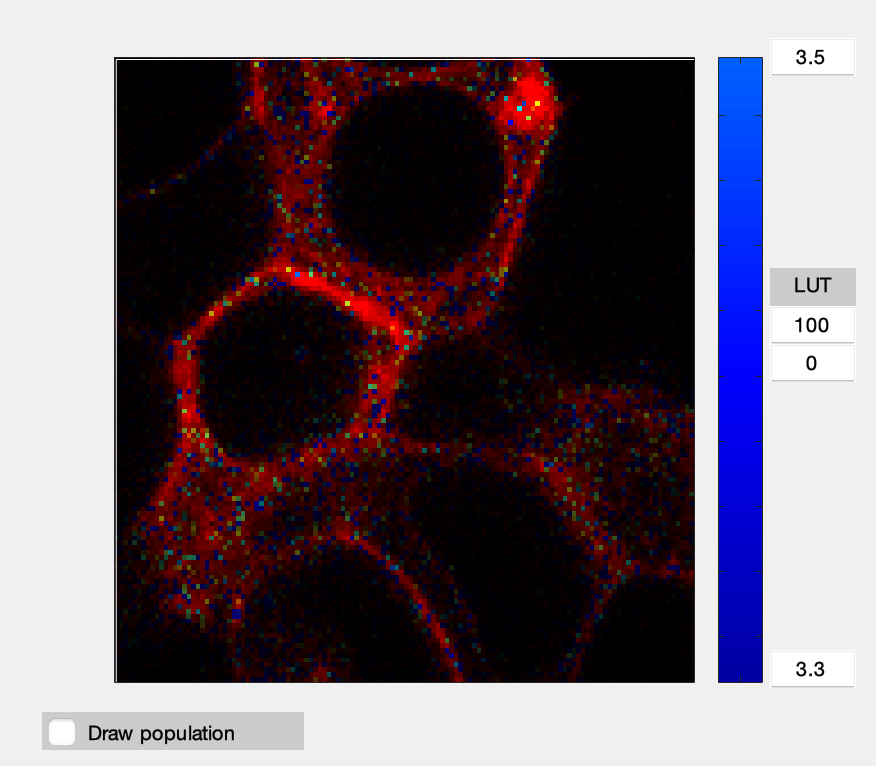

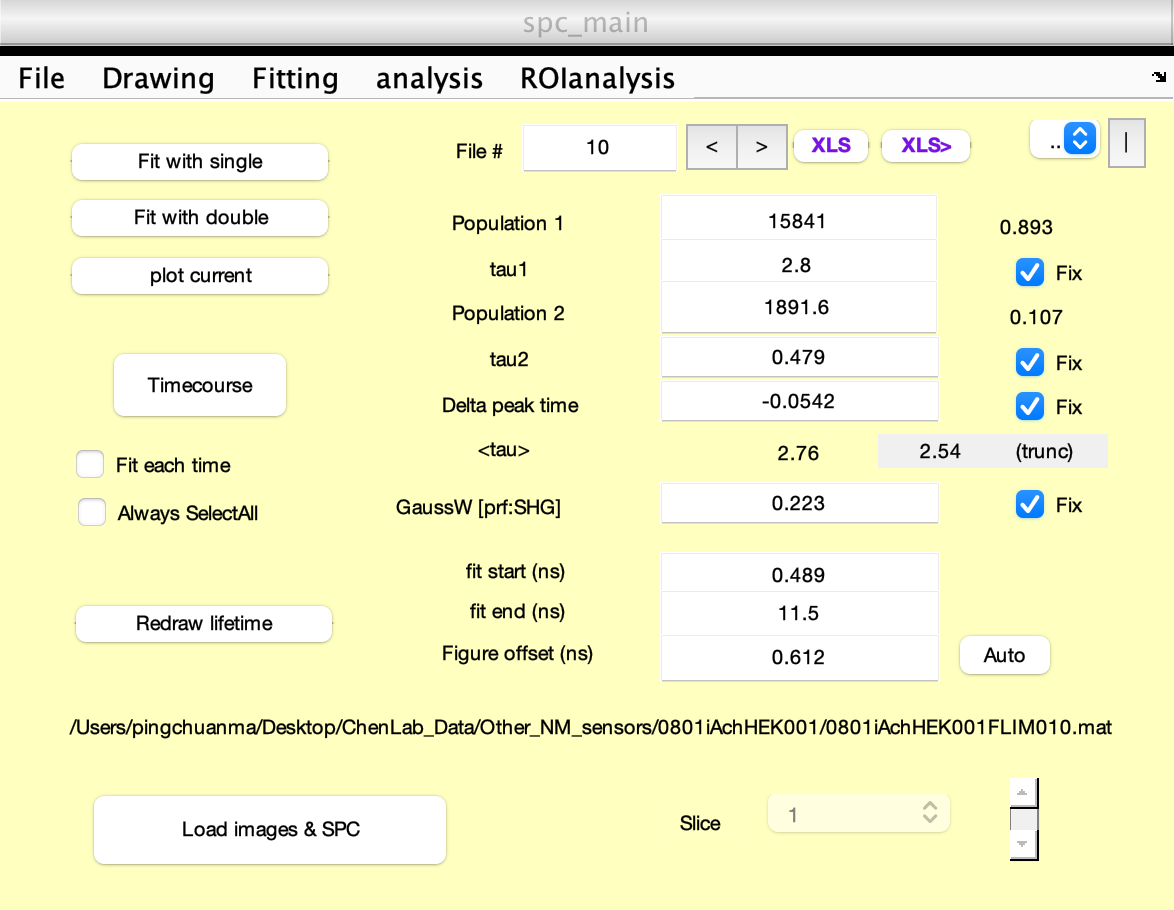

CyclePositions =      1     2


epoch_response_intensity_norm_all = 1×2 cell array
    {2×5 double}    {2×6 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×5 double}    {2×6 double}


epoch_response_intensity_all = 1×2 cell array
    {2×5 double}    {2×6 double}


epoch_response_lft_all = 1×2 cell array
    {2×5 double}    {2×6 double}



for i_file = 5

    cd(datapath{i_file});
    load(StateYao_file{i_file});
    
    CyclePositions = 1:1:size(stateYao.CyclePositions, 2)
    
    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all, FigureVisible)
    CyclePositions_in_name = '';
    for i_CycleName = 1:length(CyclePositions)
        CyclePositions_in_name = [CyclePositions_in_name, '_', num2str(CyclePositions(i_CycleName))];
    end
    currTime = datestr(datetime('now'));
    currTime = currTime(1:11);
    SavedFileName = [stateYao.baseName, '_', currTime, CyclePositions_in_name, '.mat'];
    summary_files{i_file} = SavedFileName;
    copyfile(SavedFileName, summary_path)
end



for i_file = 7:8

    cd(datapath{i_file});
    load(StateYao_file{i_file});
    
    CyclePositions = 1:1:size(stateYao.CyclePositions, 2)
    
    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all, FigureVisible)
    CyclePositions_in_name = '';
    for i_CycleName = 1:length(CyclePositions)
        CyclePositions_in_name = [CyclePositions_in_name, '_', num2str(CyclePositions(i_CycleName))];
    end
    currTime = datestr(datetime('now'));
    currTime = currTime(1:11);
    SavedFileName = [stateYao.baseName, '_', currTime, CyclePositions_in_name, '.mat'];
    summary_files{i_file} = SavedFileName;
    copyfile(SavedFileName, summary_path)
end

CyclePositions =      1     2     3


epoch_response_intensity_norm_all = 1×3 cell array
    {2×2 double}    {2×2 double}    {2×2 double}


epoch_response_lft_norm_all = 1×3 cell array
    {2×2 double}    {2×2 double}    {2×2 double}


epoch_response_intensity_all = 1×3 cell array
    {2×2 double}    {2×2 double}    {2×2 double}


epoch_response_lft_all = 1×3 cell array
    {2×2 double}    {2×2 double}    {2×2 double}


CyclePositions =      1     2


epoch_response_intensity_norm_all = 1×2 cell array
    {2×4 double}    {2×3 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×4 double}    {2×3 double}


epoch_response_intensity_all = 1×2 cell array
    {2×4 double}    {2×3 double}


epoch_response_lft_all = 1×2 cell array
    {2×4 double}    {2×3 double}





for i_file = 10

    cd(datapath{i_file});
    load(StateYao_file{i_file});
    
    CyclePositions = 1:1:size(stateYao.CyclePositions, 2)
    
    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all, FigureVisible)
    CyclePositions_in_name = '';
    for i_CycleName = 1:length(CyclePositions)
        CyclePositions_in_name = [CyclePositions_in_name, '_', num2str(CyclePositions(i_CycleName))];
    end
    currTime = datestr(datetime('now'));
    currTime = currTime(1:11);
    SavedFileName = [stateYao.baseName, '_', currTime, CyclePositions_in_name, '.mat'];
    summary_files{i_file} = SavedFileName;
    copyfile(SavedFileName, summary_path)
end

CyclePositions =      1     2


epoch_response_intensity_norm_all = 1×2 cell array
    {2×4 double}    {2×3 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×4 double}    {2×3 double}


epoch_response_intensity_all = 1×2 cell array
    {2×4 double}    {2×3 double}


epoch_response_lft_all = 1×2 cell array
    {2×4 double}    {2×3 double}


all_epochs = [2 3 4 5]; % all the epochs
drug_epochs = [2 3 4 5];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)
for i_file = 4

    cd(datapath{i_file});
    load(StateYao_file{i_file});
    
    CyclePositions = 1:1:size(stateYao.CyclePositions, 2)
    
    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all, FigureVisible)
    CyclePositions_in_name = '';
    for i_CycleName = 1:length(CyclePositions)
        CyclePositions_in_name = [CyclePositions_in_name, '_', num2str(CyclePositions(i_CycleName))];
    end
    currTime = datestr(datetime('now'));
    currTime = currTime(1:11);
    SavedFileName = [stateYao.baseName, '_', currTime, CyclePositions_in_name, '.mat'];
    summary_files{i_file} = SavedFileName;
    copyfile(SavedFileName, summary_path)
end

CyclePositions =      1     2


epoch_response_intensity_norm_all = 1×2 cell array
    {3×3 double}    {3×3 double}


epoch_response_lft_norm_all = 1×2 cell array
    {3×3 double}    {3×3 double}


epoch_response_intensity_all = 1×2 cell array
    {3×3 double}    {3×3 double}


epoch_response_lft_all = 1×2 cell array
    {3×3 double}    {3×3 double}


FigureVisible = 'off'

FigureVisible = 'off'

i_file = 6;

all_epochs = [2 3 4 5]; % all the epochs
drug_epochs = [2 3 4 5];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

cd(datapath{i_file});
load(StateYao_file{i_file});

CyclePositions = 1:1:size(stateYao.CyclePositions, 2)

CyclePositions =      1     2     3



Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
EpochStartAcq_acq_num_1 = [4 40 118 151]; % for the Excel is empty (not sure why), manually find the epoch transition acq numbers and define it
CyclePosition_acq_num_1 = stateYao.CyclePositions(:,1);
EpochStartAcq = zeros(1,length(EpochStartAcq_acq_num_1));
for j = 1:length(EpochStartAcq_acq_num_1)
    EpochStartAcq(j) = find(CyclePosition_acq_num_1 == EpochStartAcq_acq_num_1(j));
end
EpochStartAcq_all{1} = EpochStartAcq;
EpochStartAcq_all{2} = EpochStartAcq;
EpochStartAcq_all{3} = EpochStartAcq;
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all, FigureVisible)

epoch_response_intensity_norm_all = 1×3 cell array
    {3×3 double}    {3×4 double}    {3×2 double}


epoch_response_lft_norm_all = 1×3 cell array
    {3×3 double}    {3×4 double}    {3×2 double}


epoch_response_intensity_all = 1×3 cell array
    {3×3 double}    {3×4 double}    {3×2 double}


epoch_response_lft_all = 1×3 cell array
    {3×3 double}    {3×4 double}    {3×2 double}


CyclePositions_in_name = '';
for i_CycleName = 1:length(CyclePositions)
    CyclePositions_in_name = [CyclePositions_in_name, '_', num2str(CyclePositions(i_CycleName))];
end
currTime = datestr(datetime('now'));
currTime = currTime(1:11);
SavedFileName = [stateYao.baseName, '_', currTime, CyclePositions_in_name, '.mat'];
summary_files{i_file} = SavedFileName;
copyfile(SavedFileName, summary_path)

i_file = 9

i_file = 9


all_epochs = [2 3 4]; % all the epochs
drug_epochs = [2 3 4];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

cd(datapath{i_file});
load(StateYao_file{i_file});

CyclePositions = 1:1:size(stateYao.CyclePositions, 2)

CyclePositions =      1     2



Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
for j = 1:length(EpochStartAcq_all)
    EpochStartAcq_all{j} = [1 EpochStartAcq_all{j}];
end
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all, FigureVisible)

epoch_response_intensity_norm_all = 1×2 cell array
    {2×2 double}    {2×2 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×2 double}    {2×2 double}


epoch_response_intensity_all = 1×2 cell array
    {2×2 double}    {2×2 double}


epoch_response_lft_all = 1×2 cell array
    {2×2 double}    {2×2 double}



CyclePositions_in_name = '';
for i_CycleName = 1:length(CyclePositions)
    CyclePositions_in_name = [CyclePositions_in_name, '_', num2str(CyclePositions(i_CycleName))];
end
currTime = datestr(datetime('now'));
currTime = currTime(1:11);
SavedFileName = [stateYao.baseName, '_', currTime, CyclePositions_in_name, '.mat'];
summary_files{i_file} = SavedFileName;
copyfile(SavedFileName, summary_path)


cd(summary_path)
save('summary_files_20230130.mat', 'summary_files')

cd(summary_path)
load('summary_files_20230130.mat')

DA_index = [1 2]

DA_index =      1     2


iACh_index = [5]

iACh_index = 5

NE_index = [4 8 9]

NE_index =      4     8     9


HT_index = [3 6 7 10]

HT_index =      3     6     7    10


% DA

lft_norm_all_DA = [];
intensity_norm_all_DA = [];

for i_file = 1:length(DA_index)
    load(summary_files{DA_index(i_file)})

    for j = 1:length(epoch_response_lft_norm_all)
        lft_norm_all_DA = [lft_norm_all_DA epoch_response_lft_norm_all{j} NaN(2,1)];
        intensity_norm_all_DA = [intensity_norm_all_DA epoch_response_intensity_norm_all{j} NaN(2,1)];
    end

end

% iACh
lft_norm_all_iACh = [];
intensity_norm_all_iACh = [];

for i_file = 1:length(iACh_index)
    load(summary_files{iACh_index(i_file)})

    for j = 1:length(epoch_response_lft_norm_all)
        lft_norm_all_iACh = [lft_norm_all_iACh epoch_response_lft_norm_all{j} NaN(2,1)];
        intensity_norm_all_iACh = [intensity_norm_all_iACh epoch_response_intensity_norm_all{j} NaN(2,1)];
    end

end

% NE
lft_norm_all_NE = [];
intensity_norm_all_NE = [];

for i_file = 1:length(NE_index)
    load(summary_files{NE_index(i_file)})

    for j = 1:length(epoch_response_lft_norm_all)
        lft_norm_all_NE = [lft_norm_all_NE epoch_response_lft_norm_all{j}([1 end],:) NaN(2,1)];
        intensity_norm_all_NE = [intensity_norm_all_NE epoch_response_intensity_norm_all{j}([1 end],:) NaN(2,1)];
    end

end

% 5HT
lft_norm_all_HT = [];
intensity_norm_all_HT = [];

for i_file = 1:length(HT_index)
    load(summary_files{HT_index(i_file)})

    for j = 1:length(epoch_response_lft_norm_all)
        lft_norm_all_HT = [lft_norm_all_HT epoch_response_lft_norm_all{j}([1 end],:) NaN(2,1)];
        intensity_norm_all_HT = [intensity_norm_all_HT epoch_response_intensity_norm_all{j}([1 end],:) NaN(2,1)];
    end

end

save('summary_data_20230130.mat', 'lft_norm_all_DA', 'intensity_norm_all_DA', 'lft_norm_all_iACh', 'intensity_norm_all_iACh','lft_norm_all_NE', 'intensity_norm_all_NE','lft_norm_all_HT', 'intensity_norm_all_HT')